#  Multi-layered and spherically-symmetric Io, tidal heating 

In this notebook the tidal response of a multi-layered, spherically-symmetric, viscoelastic body is computed using LOV3D and the resulting tidal dissipation distribution ploted. 

clearvars
clc
set(0,'defaulttextInterpreter','latex') 
mfile_name          = mfilename('fullpath');
if contains(mfile_name,'LiveEditorEvaluationHelper')
    mfile_name=matlab.desktop.editor.getActiveFilename;
end
[pathstr,name,ext]  = fileparts(mfile_name);
cd(pathstr);
cd('..')
addpath(genpath(pwd))

## Interior model

The interior model is based on the Io model of [Steinke et al. 2023](https://doi.org/10.1016/j.icarus.2019.05.001) and [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw), which consists on a core, mantle, asthenosphere and lithosphere. Three different interior models are considered

- Interior Model A: Tidal heating only occurs in the asthenosphere (based on [Steinke et al. 2023](https://doi.org/10.1016/j.icarus.2019.05.001) ) 

- Interior Model B: Tidal heating occurs in both asthenosphere and deep mantle (based on [Steinke et al. 2023](https://doi.org/10.1016/j.icarus.2019.05.001))

- Interior Model C: Tidal heating occurs in both layers (based on  [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw))

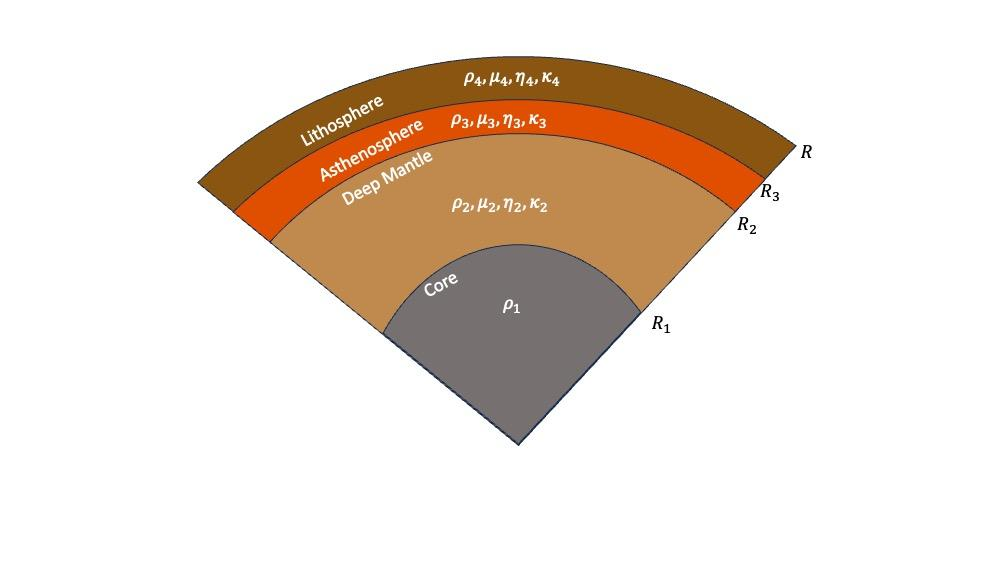

Any of the models can be selected by seting Interior_Model to Interior_Model_X

% Values are taken from Steinke et al. (2020a)
omega0=4.1086E-05; %Io's orbital frequency 
T=2*pi/omega0; %Io's orbital period
% Interior model A, asthenosphere only heating 
% Interior_Model goes from core (1) to surface (n) with indices
% Interior_Model values for the core
Interior_Model_A(1).R0 = 965; % CMB in km 
Interior_Model_A(1).rho0 = 5150; % average density in kg m^-3
Interior_Model_A(1).rho0_2 = 5150; % rho_2 in kg m^-3 (used for icy moons)
% Interior_Model values for mantle
Interior_Model_A(2).R0 = 1591.6; % outer radius of this layer
Interior_Model_A(2).rho0 = 3244; % density in kg m^-3
Interior_Model_A(2).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_A(2).mu0 = 6e10; % shear modulus in Pa
Interior_Model_A(2).eta0 = 1e20; % viscosity in Pa s
% Interior_Model values for asthenosphere
Interior_Model_A(3).R0 = 1791.6; % outer radius of this layer
Interior_Model_A(3).rho0 = 3244; % density in kg m^-3
Interior_Model_A(3).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_A(3).mu0 = 7.8e5; % shear modulus in Pa
Interior_Model_A(3).eta0 = 1e11; % viscosity in Pa s
% Interior_Model values for mantle
Interior_Model_A(4).R0 = 1821.6; % outer radius of this layer
Interior_Model_A(4).rho0 = 3244; % density in kg m^-3
Interior_Model_A(4).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_A(4).mu0 = 6.5e10; % shear modulus in Pa
Interior_Model_A(4).eta0 = 1e23; % viscosity in Pa s
% Interior model B, mixed heating
% Interior_Model values for the core
Interior_Model_B(1).R0 = 965; % CMB in km 
Interior_Model_B(1).rho0 = 5150; % average density in kg m^-3
Interior_Model_B(1).rho0_2 = 5150; % rho_2 in kg m^-3 (used for icy moons)
% Interior_Model values for mantle
Interior_Model_B(2).R0 = 1591.6; % outer radius of this layer
Interior_Model_B(2).rho0 = 3244; % density in kg m^-3
Interior_Model_B(2).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_B(2).mu0 = 2e9; % shear modulus in Pa
Interior_Model_B(2).eta0 = 8e14; % viscosity in Pa s
% Interior_Model values for asthenosphere
Interior_Model_B(3).R0 = 1791.6; % outer radius of this layer
Interior_Model_B(3).rho0 = 3244; % density in kg m^-3
Interior_Model_B(3).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_B(3).mu0 = 9e7; % shear modulus in Pa
Interior_Model_B(3).eta0 = 3.5e12; % viscosity in Pa s
% Interior_Model values for mantle
Interior_Model_B(4).R0 = 1821.6; % outer radius of this layer
Interior_Model_B(4).rho0 = 3244; % density in kg m^-3
Interior_Model_B(4).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_B(4).mu0 = 6.5e10; % shear modulus in Pa
Interior_Model_B(4).eta0 = 1e23; % viscosity in Pa s

% Interior Model C (Beuthe 2013)
Interior_Model_C(1).R0 = 716; % CMB in km 
Interior_Model_C(1).rho0 = 6767; % average density in kg m^-3
% Interior_Model values for mantle
Interior_Model_C(2).R0 = 716+1026; % outer radius of this layer
Interior_Model_C(2).rho0 = 3349; % density in kg m^-3
Interior_Model_C(2).Ks0 = 200e15; % bulk modulus in Pa
Interior_Model_C(2).mu0 = 10e9; % shear modulus in Pa
Interior_Model_C(2).eta0 = 1e15; % viscosity in Pa s
% Interior_Model values for asthenosphere
Interior_Model_C(3).R0 = 716+1026+50; % outer radius of this layer
Interior_Model_C(3).rho0 = 3349; % density in kg m^-3
Interior_Model_C(3).Ks0 = 200e15; % bulk modulus in Pa
Interior_Model_C(3).mu0 = 5e4; % shear modulus in Pa
Interior_Model_C(3).eta0 = 2.5e10; % viscosity in Pa s
% Interior_Model values for mantle
Interior_Model_C(4).R0 = 716+1026+50+30; % outer radius of this layer
Interior_Model_C(4).rho0 = 2750; % density in kg m^-3
Interior_Model_C(4).Ks0 = 200e15; % bulk modulus in Pa
Interior_Model_C(4).mu0 = 7e10; % shear modulus in Pa
Interior_Model_C(4).eta0 = 1e20; % viscosity in Pa s

Interior_Model=Interior_Model_B; 

## Define forcing

The forcing potential is that of a moon in an eccentric orbit. Note that the tidal potential is  normalized by (omega)^2e

Forcing(1).Td=2*pi/omega0;
Forcing(1).n=2; 
Forcing(1).m=0; 
Forcing(1).F=3/4*sqrt(1/5); 
Forcing(2).Td=2*pi/omega0;
Forcing(2).n=2; 
Forcing(2).m=-2; 
Forcing(2).F=-7/8*sqrt(6/5);
Forcing(3).Td=2*pi/omega0;
Forcing(3).n=2; 
Forcing(3).m=2; 
Forcing(3).F=1/8*sqrt(6/5);

## Define numerics used to compute the tidal response 

%radial discretization
Numerics.Nlayers = length(Interior_Model); % number of concentric layers. Including the core!
Numerics.method = 'variable'; % method of setting the radial points per layer, here fixed number of layers
Numerics.Nrbase = 100; % depending on the method this will determine the number of points per layer
%code parallelization
Numerics.parallel_sol = 0; % Use a parfor-loop to call get_Love, either 0 or 1
Numerics.parallel_gen = 0; % Calculate potential coupling files and the propagation inside get_solution using parfor-loops, either 0 or 1
% lateral variations
Numerics.perturbation_order = 2; %maximum order to which couplings are considered
Numerics.solution_cutoff = 12; % maximum degree of solution, not used if perturbation order is specified
Numerics.load_couplings = 1; % 0=no loading, 1=loading of specific file, 2=searches for big enough file
Numerics.Nenergy = 12; % maximum degree to which energy dissipation is expanded 
Numerics.rheology_cutoff = 2; % maximum order of difference (so in log) up to which rheology is still used 
Numerics.coupling_file_location = 'data/couplings/'; % MUST END WITH A '/' , Location where coupling files are saved or should be saved 
[Numerics, Interior_Model] = set_boundary_indices(Numerics, Interior_Model,'verbose');

Inside set_boundary_indices: 
Nrlayer: 0  100  100  100
BCindices: 101  201  301
Nr: 300
 


## Compute the tidal response 

The tidal response is obtained for models A and B 

% write interior model in the right format for the code
Interior_Model= get_rheology(Interior_Model,Numerics,Forcing);

No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 


No lateral variations provided for layer 3, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 4, I will assume the layer is spherically-symmetric 


for i=1:length(Forcing)
    [Love_Spectra(i),y(i)]=get_Love(Interior_Model,Forcing(i),Numerics,'verbose');
end

Obtaining Couplings....
Only uniform layers so coupling matrix is zero
------------- INTERIOR MODEL ----------- 
AVERAGE PROPERTIES (dimensional)
Layer#     R[m]    rho[kg.m^{-3}]    mu[Pa]    K[Pa]    eta[Pa.s]
1    9.65000e+02    5.15000e+03    0    -
2    1.59160e+03    3.24400e+03    2.00000e+09    2.00000e+14 8.00000e+14
3    1.79160e+03    3.24400e+03    9.00000e+07    2.00000e+14 3.50000e+12
4    1.82160e+03    3.24400e+03    6.50000e+10    2.00000e+14 1.00000e+23
AVERAGE PROPERTIES (non-dimensional)
Layer#     R[-]    rho[-]    mu[-]    K [-]     eta[-]
1    0.52975    1.5875    0    -
2    0.87374    1    0.030769    3076.9231 0.08048
3    0.98353    1    0.0013846    3076.9231 0.0003521
4    1    1    1    3076.9231 10060061.526
RHEOLOGY  VARIATIONS
Shear Modulus
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
2    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
3    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^

## Compute tidal heating 

Computes tidal dissipation 


$$\dot{e}(r,\theta,\varphi)=\frac{1}{T}\int_t^{t+T}\sigma(r,\theta,\varphi,t):\dot\epsilon(r,\theta,\varphi,t)dt$$


in terms of spherical harmonics


$$\dot{e}=\sum_{n,m}e_n^m(r)Y_n^m(\theta,\varphi)$$


[Energy_Spectra]=get_energy(y,Numerics,Forcing,Interior_Model);

Check that tidal heating computed using 


$$E=4\pi\int e_0 r^2 dr$$


and using the work done by the tidal force are equivalent 


$$\dot{E}=\frac{1}{T}\int_V\int_T\rho\frac{\partial{u}}{\partial t} \cdot\nabla\phi^TdtdV$$


E_k=0;
for i=1:length(Forcing)
    n_f=Forcing(i).n;
    m_f=Forcing(i).m;
    for j=1:length(Forcing)
        ind1=find(Love_Spectra(j).n==n_f & Love_Spectra(j).m==m_f);
        if isempty(ind1)==0
            E_k=E_k-Forcing(i).F*Forcing(j).F*imag(Love_Spectra(j).k(ind1));
        end
    end
end
e_01_Uni=2*pi*10/(4*pi*Interior_Model(end).Gg)*E_k;
e_02_Uni=Energy_Spectra.energy_integral(1);

disp(['Difference between tidal heating computed using the two methods ' num2str(real(abs(e_01_Uni - e_02_Uni)) ./ e_01_Uni * 100) ' %'])

Difference between tidal heating computed using the two methods 0.57837 %


The dimensional tidal heating [W/m2] can be recovered by using (see manual)


$$\dot{e}=\frac{\rho(N)^2\omega^4R(N)^5e^2}{T\mu_0(N)}$$


G=6.67e-11;
ecc=4e-3; %Io eccentricity 
rho_0=Interior_Model(end).rho0; %density of uppermost layer
R_0=Interior_Model(end).R0*1e3; %surface radius in m
mu_0=Interior_Model(end).mu0; %shear modulus of uppermost layer 
scale=omega0^2*R_0^2*ecc*rho_0/mu_0; %scale for the tidal potential 
%uniform 
e_mean_dimensional=R_0*scale^2*mu_0/T*Energy_Spectra.energy_integral(1); %(in W/m2)
disp(['The average tidal heating is ' num2str(e_mean_dimensional) ' Wm^{-2}'])

The average tidal heating is 2.1153 Wm^{-2}


## Plot the distribution of tidal heating 

Plot the normalaized (with the mean value), tidal heating. Dimensional units can be simply obtained by multiplying by e_mean_dimensional

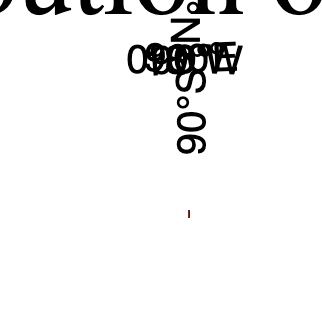

Energy_Spectra_Norm=Energy_Spectra; 
Energy_Spectra_Norm.energy_integral_v=Energy_Spectra_Norm.energy_integral_v/Energy_Spectra.energy_integral_v(1);
plot_energy_map(Energy_Spectra_Norm,'type','total','projection','mollweide','title','Spatial Distribution of Tidal Heating');

## Compute the spatial y functions and plot them

Here, the radial functions are transformed to the spatial domain and the fields plotted for a specific point 

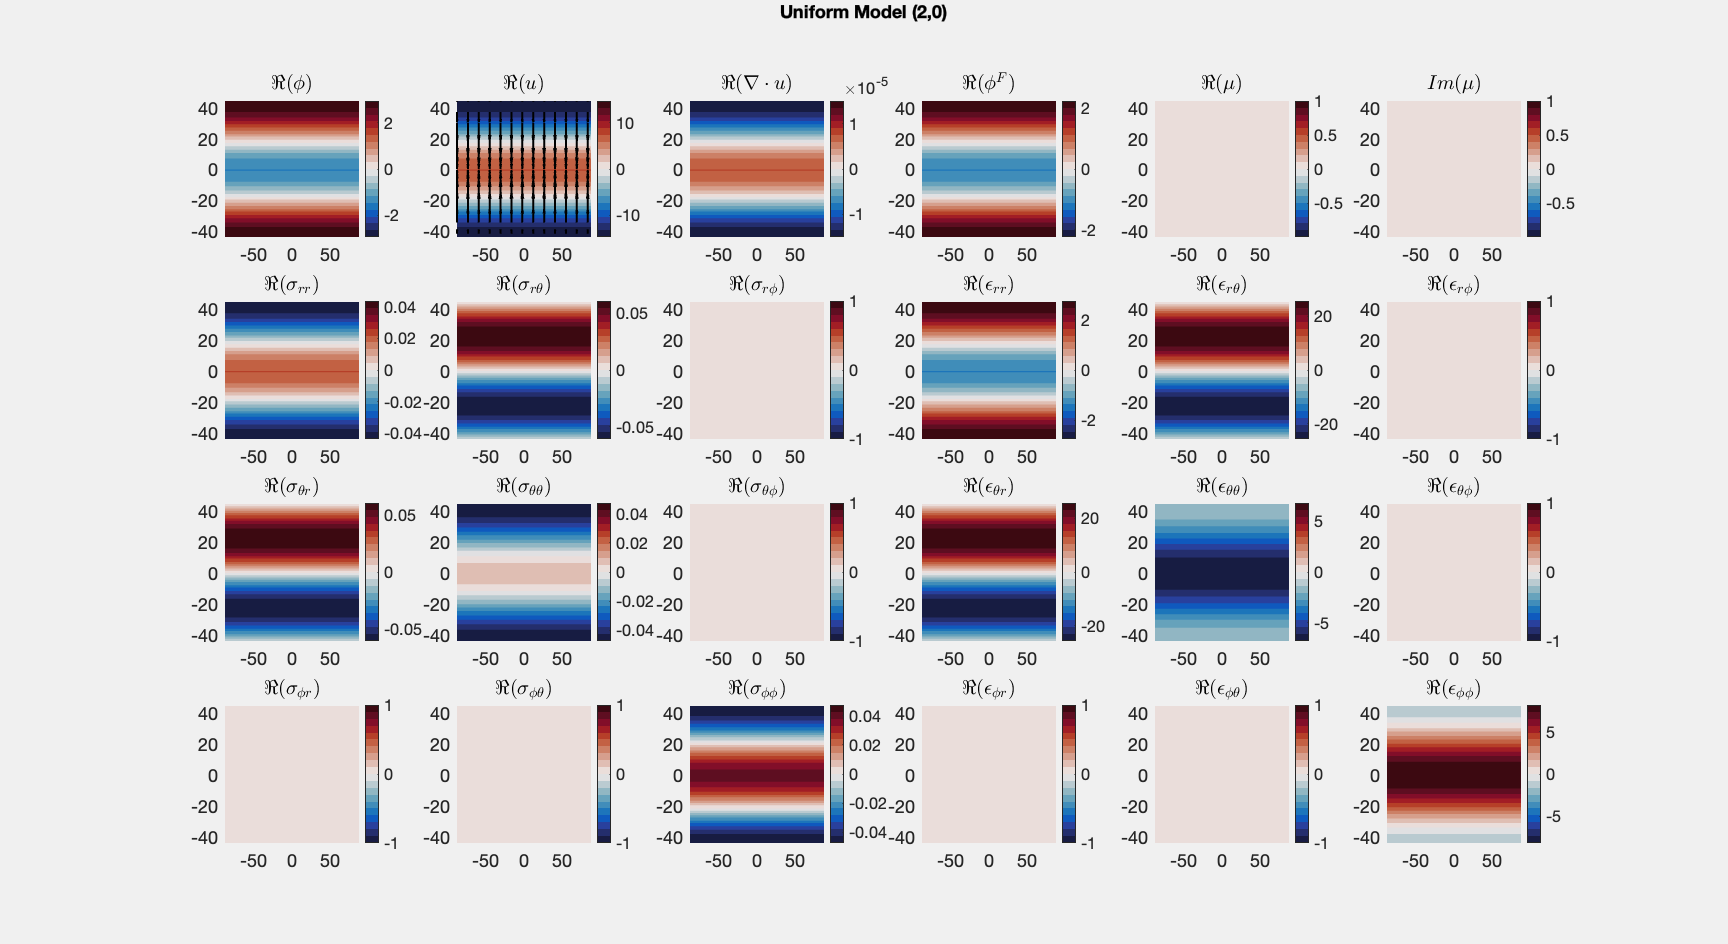

% The y functions given in spherical harmonics are mapped to a lat lon and some relavnt tensors are plotted.  
% First we need to define the radial point for which we want the plot 
r=0.9;
[a, indP]=min(abs(r-y(1).y(:,1)));
for k=2:length(Interior_Model)
    if r>Interior_Model(k-1).R && r<Interior_Model(k).R
        indL=k;
    end
end
% We convert the y function from the spectral to the spatial domain 
[y_LatLon] = get_map(y(1),Interior_Model(indL));
%plot the gravitational potential, displacements and strain and stress tensors for the uniform model 
plot_map(y_LatLon,Interior_Model(indL),'field_name','all','radial_point',indP,'plot_title','Uniform Model (2,0)')

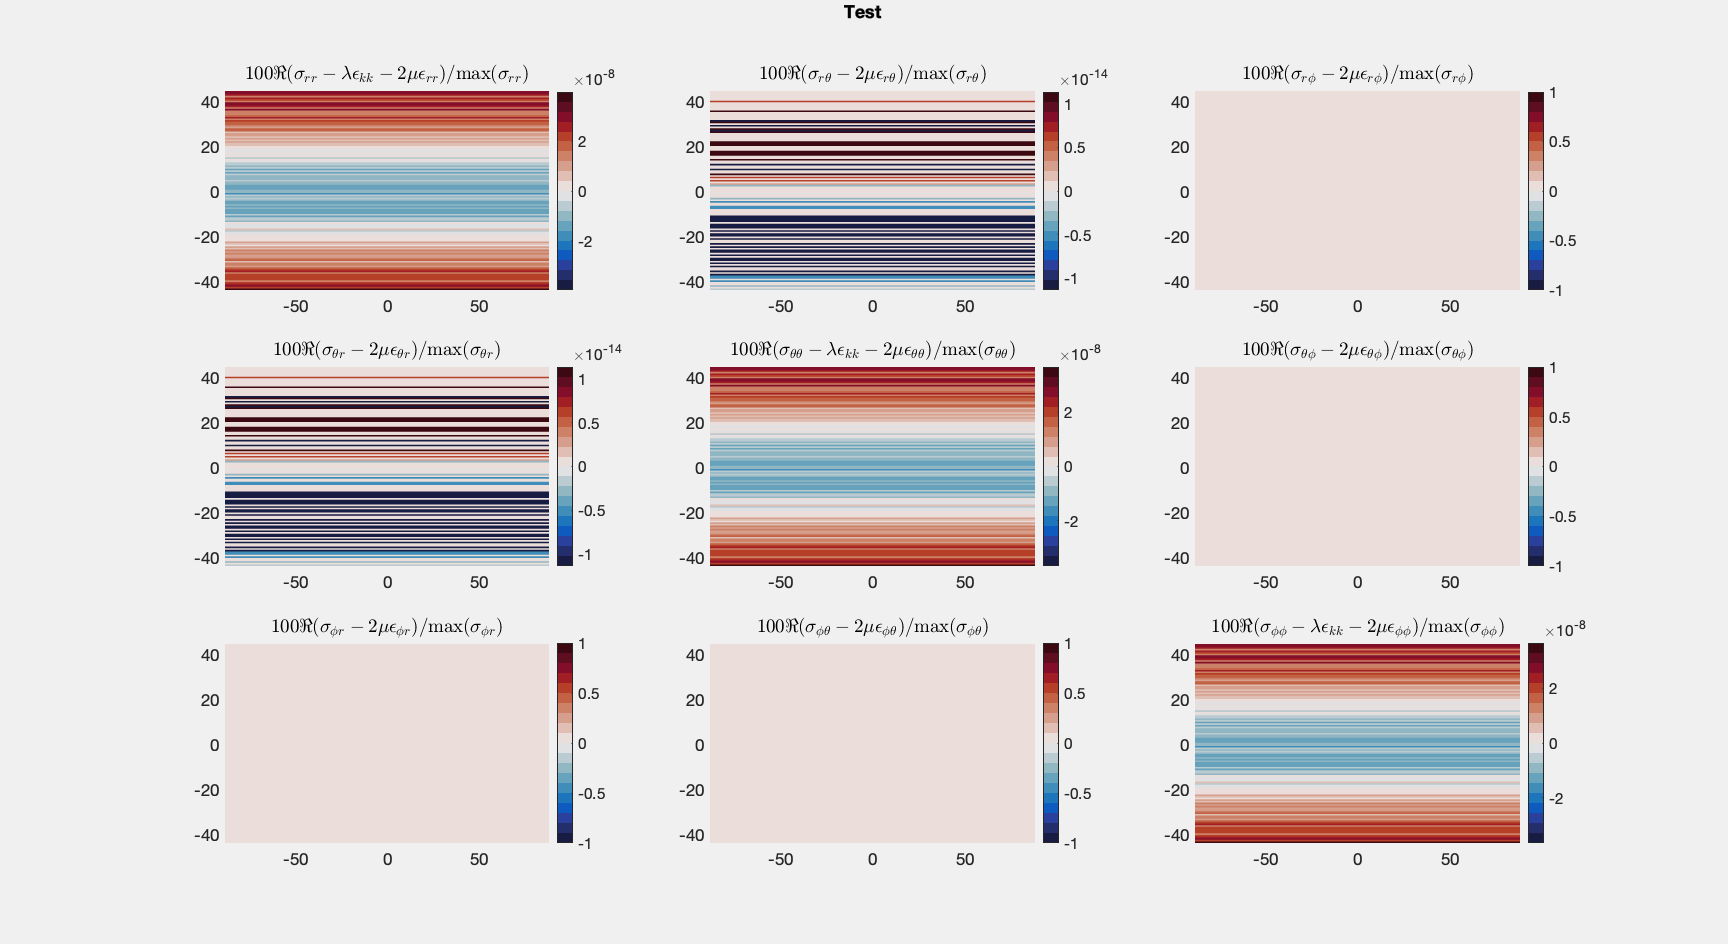

% As a consistency check we can also plot the strain and stress tensors computed usung two methods. 
% The residuals should be close to 0.
plot_map(y_LatLon,Interior_Model(indL),'field_name','test_strain_stress','radial_point',indP,'plot_title','Test');